# Bernstein approximation

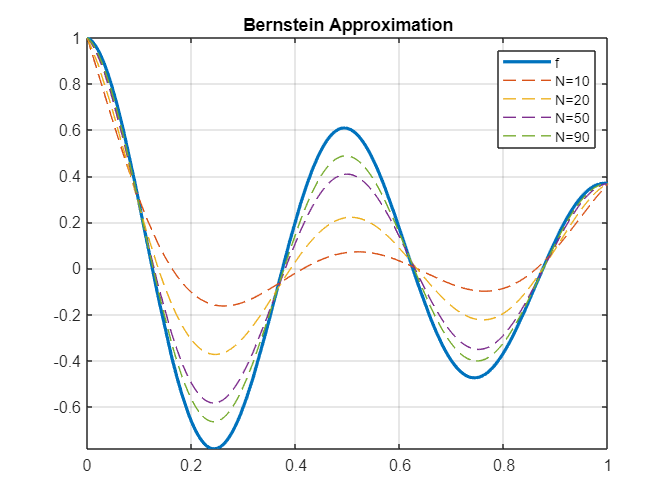

syms x real
f = cos(4*pi*x).* exp(-x); % f is continuous on [0 1] ( another symbolic object )

figure
fplot(f, [0,1], LineWidth=2)
hold on
grid on
title("Bernstein Approximation")

Bf = cell(4,1);
i = 1;
for N = [10,20,50,90]
    Bf{i}= bernstein(f, N, x); % computing Bernstein polynomials using de Casteljau 's algorithm
    fplot(Bf{i}, [0,1], '--')
    i = i+1;
end
legend(["f" "N="+ [10,20,50,90]])

Expression of the Bernstein approximation for N=10:

B10 = Bf{1}

$$B10 = \begin{array}{l} {\left(x-1\right)}^{10}+x^{10}\,{\mathrm{e}}^{-1}-252\,x^{5}\,{\mathrm{e}}^{-\frac{1}{2}}\,{\left(x-1\right)}^{5}-10\,x\,{\mathrm{e}}^{-\frac{1}{10}}\,\sigma_{1}\,{\left(x-1\right)}^{9}-10\,x^{9}\,{\mathrm{e}}^{-\frac{9}{10}}\,\sigma_{1}\,\left(x-1\right)-45\,x^{2}\,{\mathrm{e}}^{-\frac{1}{5}}\,\sigma_{2}\,{\left(x-1\right)}^{8}+210\,x^{4}\,{\mathrm{e}}^{-\frac{2}{5}}\,\sigma_{1}\,{\left(x-1\right)}^{6}+210\,x^{6}\,{\mathrm{e}}^{-\frac{3}{5}}\,\sigma_{1}\,{\left(x-1\right)}^{4}-45\,x^{8}\,{\mathrm{e}}^{-\frac{4}{5}}\,\sigma_{2}\,{\left(x-1\right)}^{2}+120\,x^{3}\,{\mathrm{e}}^{-\frac{3}{10}}\,\sigma_{2}\,{\left(x-1\right)}^{7}+120\,x^{7}\,{\mathrm{e}}^{-\frac{7}{10}}\,\sigma_{2}\,{\left(x-1\right)}^{3}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{5}}{4}-\frac{1}{4}\\ \sigma_{2}=\frac{\sqrt{5}}{4}+\frac{1}{4} \end{array}$$

or 

B10 = expand(Bf{1})